## Housekeeping Commands

close all
clear
clc

## Layout of Imported Tables

%{
CastIronProperties.txt
    column 1: ASTM Number
    column 2: Minimum Young's Modulus [Mpsi]
    column 3: Maximum Young's Modulus [Mpsi]

SteelProperties.txt
    column 1: AISI Number
    column 2: Young's Modulus [GPa]

BoltClass8-8Properties.txt
    column 1: Nominal Size [mm]
    column 2: Bolt Length [mm]
    column 3: Thread Length [mm]
    column 4: Bolt Head Width [mm]

BoltClass10-9Properties.txt
    column 1: Nominal Size [mm]
    column 2: Bolt Length [mm]
    column 3: Thread Length [mm]
    column 4: Bolt Head Width [mm]

metricNutProperties.txt
    column 1: Nominal Size [mm]
    column 2: Width [mm]

Table8-1.txt
    column 1: Nominal Diameter [mm]
    column 2: Pitch [mm]
    column 3: Tensile-Stress Area [mm^2]
    column 4: Minor-Diameter Area [mm^2]
%}

## Determine Factors of Safety

syms k_m k_b d alpha T_1 T_2
syms E k D t [3 1]

alpha = 30*(pi()/180);
% Units of mm
T_1 = 25;
% Units of mm
T_2 = 30;
% Units of mm
T_tot = T_1 + T_2;

ironChoice = [];
[ironChoice, E(1)] = chooseIron(ironChoice);
steelChoice = [];
[steelChoice, E(2)] = chooseSteel(steelChoice);
boltClassChoice = [];
boltChoice = [];
[boltClassChoice, boltChoice, ~, D(1), d, ~, ~, ~, ~, ~] = chooseBoltClass(boltClassChoice, boltChoice, T_tot);

t(1) = T_1;
t(2) = T_2 - 0.5*(T_1 + T_2);
t(3) = T_2 - t(2);

D(2) = D(1) + 2*t(1)*tan(alpha);
D(3) = D(1);

k(1) = (pi()*E(1)*d*tan(alpha)) / (log(((2*t(1)*tan(alpha) + D(1) - d)*(D(1)+d)) / ((2*t(1)*tan(alpha) + D(1) + d)*(D(1)-d))));
k(2) = (pi()*E(2)*d*tan(alpha)) / (log(((2*t(2)*tan(alpha) + D(2) - d)*(D(2)+d)) / ((2*t(2)*tan(alpha) + D(2) + d)*(D(2)-d))));
k(3) = (pi()*E(2)*d*tan(alpha)) / (log(((2*t(3)*tan(alpha) + D(3) - d)*(D(3)+d)) / ((2*t(3)*tan(alpha) + D(3) + d)*(D(3)-d))));
k_m = (k(1)^-1 + k(2)^-1 + k(3)^-1)^-1;

syms A_t A_d l L L_t l_t l_d
[boltClassChoice, boltChoice, E(3), ~, ~, L, L_t, ~, ~, ~] = chooseBoltClass(boltClassChoice, boltChoice, T_tot);
[~, A_t, ~] = boltSizeProperties(d);
l = T_tot;

l_d = L - L_t;
l_t = l - l_d;
A_d = (pi()*d^2) / 4;
k_b = (A_d*A_t*E(3)) / (A_d*l_t + A_t*l_d);

syms C P P_tot N F_p F_i S_p n_p n_L n_O n_f sigma_i sigma_a sigma_m S_e S_ut
[boltClassChoice, boltChoice, E(3), ~, ~, ~, ~, S_p, S_ut, S_e] = chooseBoltClass(boltClassChoice, boltChoice, T_tot);
% Units of mm
sealingDiameter = 100;
% Units of N
P_tot = 10*(pi()*(sealingDiameter/2)^2);
P_tot = P_tot * 1e-3; % Conversion to kN

% Units of N
P_tot_fluc = 3*(pi()*(sealingDiameter/2)^2);
P_tot_fluc = P_tot_fluc * 1e-3; % Conversion to kN

C = k_b / (k_b + k_m);
% Units of N
F_p = A_t*S_p;
F_p = F_p / 1e3; % Conversion to kN
% Units of kN
F_i = 0.9*F_p;

counter = 1;
n_L = 0;
while n_L < 2
    N = counter;

    % Units of kN/bolt
    P = P_tot / N;
    % Units of kN/bolt
    P_fluc = P_tot_fluc / N;
    
    % Units of GPa
    sigma_i = (F_i / A_t) * 1e3; % Conversion to MPa
    % Units of GPa
    sigma_a = ((C*P_fluc) / (2*A_t)) * 1e3; % Conversion to MPa
    % Units of MPa
    sigma_m = sigma_a + sigma_i;

    n_p = (F_p) / (C*P + F_i);
    n_L = (F_p - F_i) / (C*P);
    n_O = F_i / (P*(1 - C));
    n_f = (S_e*(S_ut - sigma_i)) / ((S_ut*sigma_a) + S_e*(sigma_m - sigma_i));
    counter = counter + 1;
end

N = vpa(N)

$$N = 11.0$$

n_p = vpa(n_p)

$$n\_p = 1.0551680615275766913453488237605$$

n_L = vpa(n_L)

$$n\_L = 2.0957187103327573049791103271441$$

n_O = vpa(n_O)

$$n\_O = 4.8045704212548058662948934203314$$

n_f = vpa(n_f)

$$n\_f = 6.6472468445933255977746894926277$$


loadLine = @(x) (sigma_a/(sigma_m-sigma_i))*(x-sigma_i)

loadLine = function_handle with value:
    @(x)(sigma_a/(sigma_m-sigma_i))*(x-sigma_i)


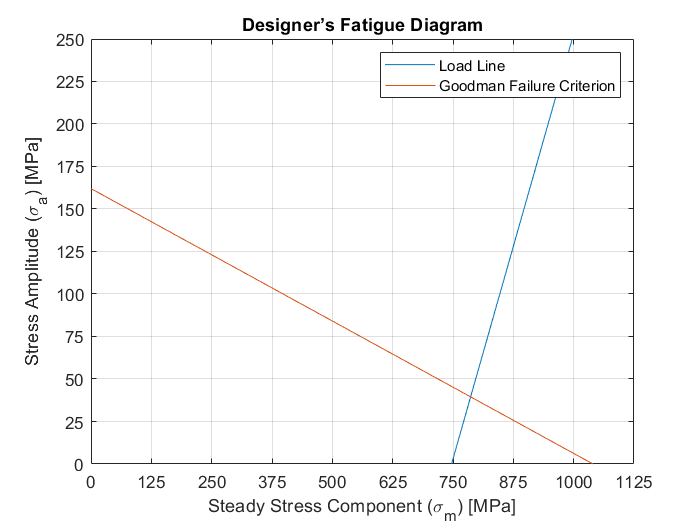

fplot(loadLine,[sigma_i 1000])
hold on
plot([0 S_ut],[S_e 0])
grid on
title('Designer’s Fatigue Diagram')
legend('Load Line','Goodman Failure Criterion')
xlabel('Steady Stress Component (\sigma_{m}) [MPa]')
xlim([0 1125])
xticks(0:125:1125)
ylabel('Stress Amplitude (\sigma_{a}) [MPa]')
ylim([0 250])
yticks(0:25:250)

function [ironChoice, modulus] = chooseIron(ironChoice)
% Values in imported file gotten from Table A-24 in 11th Edition Book
ironValues = importdata('CastIronProperties.txt');
if isempty(ironChoice)
    list = arrayfun(@num2str,ironValues(:,1),'un',0);
    tf = 0;
    while tf == 0
        [ironIndex,tf] = listdlg('PromptString','Chosen Cast Iron ASTM number:','SelectionMode','single','ListString',list);
    end
    ironChoice = ironIndex;
end

% Values in file are all in Mpsi
modulus = ironValues(ironChoice,2)*1e6 * 6.89e3; % Conversion to Pa
modulus = modulus / 1e9; % Conversion to GPa
end

function [steelChoice, modulus] = chooseSteel(steelChoice)
% Values in imported file gotten from a combination of Table A-23 in 11th Edition book
% and online website: https://www.elginfasteners.com/resources/materials/material-specifications/
steelValues = importdata('SteelProperties.txt');
if isempty(steelChoice)
    list = arrayfun(@num2str,steelValues(:,1),'un',0);
    tf = 0;
    while tf == 0
        [steelIndex,tf] = listdlg('PromptString','Chosen Steel AISI number:','SelectionMode','single','ListString',list);
    end
    steelChoice = steelIndex;
end

% Values in file are all in GPa
modulus = steelValues(steelChoice,2);
end

function [boltClassChoice, boltChoice, modulus, headDiameter, boltSize, boltLength, threadedLength, proofStrength, tensileStength, enduranceStrength] = chooseBoltClass(boltClassChoice, boltChoice, T_tot)
% Values in imported files gotten from McMaster-Carr website:
% https://www.mcmaster.com/https%3a%2f%2fwwwmcmastercom%2fbolts%2fsystem-of-measurement~metric%2fhead-type~hex%2fthreading~partially-threaded%2fmaterial~steel/threading~partially-threaded/
boltClass8Values = importdata('BoltClass8-8Properties.txt');
boltClass10Values = importdata('BoltClass10-9Properties.txt');
% Values in imported file gotten from Table A-31 from 11th Edition book
nutValues = importdata('metricNutProperties.txt');

if isempty(boltClassChoice)
    tf = 0;
    list = {'Class 8.8' 'Class 10.9'};
    while tf == 0
        [boltClassIndex,tf] = listdlg('PromptString','Choose a Metric Bolt Class:','SelectionMode','single','ListString',list);
    end
    boltClassChoice = boltClassIndex;

    switch boltClassChoice
        case 1
            [row, ~] = find(boltClass8Values(:,2) > T_tot);
            nominalDiameters = unique(boltClass8Values(row,1),'stable');
            diameterList = arrayfun(@num2str,nominalDiameters,'un',0);
            tf = 0;
            while tf == 0
                [boltSizeIndex,tf] = listdlg('PromptString','Choose a Metric Bolt Size:','SelectionMode','single','ListString',diameterList);
            end
            [nutIndex, ~] = find(nutValues(:,1) == nominalDiameters(boltSizeIndex));
            [lengthIndex1, ~] = find(boltClass8Values(:,1) == nominalDiameters(boltSizeIndex));
            [lengthIndex, ~] = find(boltClass8Values(lengthIndex1,2) > (T_tot + nutValues(nutIndex,2)));
            lengths = unique(boltClass8Values(lengthIndex1(lengthIndex),2),'stable');
            lengthList = arrayfun(@num2str,lengths,'un',0);
            tf = 0;
            while tf == 0
                [boltLengthIndex,tf] = listdlg('PromptString','Choose a Metric Bolt Length:','SelectionMode','single','ListString',lengthList);
            end
            [boltIndex1, ~] = find(boltClass8Values(:,1) == nominalDiameters(boltSizeIndex));
            [boltIndex, ~] = find(boltClass8Values(:,2) == lengths(boltLengthIndex));
            rowLocation = boltIndex(ismember(boltIndex, boltIndex1));

            boltChoice = rowLocation;
            % Units of mm
            boltSize = boltClass8Values(boltChoice, 1);
            % Units of mm
            boltLength = boltClass8Values(boltChoice, 2);
            % Units of mm
            threadedLength = boltClass8Values(boltChoice, 3);
            % Units of mm
            headDiameter = boltClass8Values(boltChoice, 4);
            % Units of MPa
            proofStrength = 600; % Value gotten from Table 8-11 in 11th Edition book
            % Units of MPa
            tensileStength = 830; % Value gotten from Table 8-11 in 11th Edition book
            % Units of MPa
            enduranceStrength = 129; % Value gotten from Table 8-17 in 11th Edition book
        case 2
            [row, ~] = find(boltClass10Values(:,2) > T_tot);
            nominalDiameters = unique(boltClass10Values(row,1),'stable');
            diameterList = arrayfun(@num2str,nominalDiameters,'un',0);
            tf = 0;
            while tf == 0
                [boltSizeIndex,tf] = listdlg('PromptString','Choose a metric bolt size:','SelectionMode','single','ListString',diameterList);
            end
            [nutIndex, ~] = find(nutValues(:,1) == nominalDiameters(boltSizeIndex));
            [lengthIndex1, ~] = find(boltClass10Values(:,1) == nominalDiameters(boltSizeIndex));
            [lengthIndex, ~] = find(boltClass10Values(lengthIndex1,2) > (T_tot + nutValues(nutIndex,2)));
            lengths = unique(boltClass10Values(lengthIndex1(lengthIndex),2),'stable');
            lengthList = arrayfun(@num2str,lengths,'un',0);
            tf = 0;
            while tf == 0
                [boltLengthIndex,tf] = listdlg('PromptString','Choose a metric bolt length:','SelectionMode','single','ListString',lengthList);
            end
            [boltIndex1, ~] = find(boltClass10Values(:,1) == nominalDiameters(boltSizeIndex));
            [boltIndex, ~] = find(boltClass10Values(:,2) == lengths(boltLengthIndex));
            rowLocation = boltIndex(ismember(boltIndex, boltIndex1));

            boltChoice = rowLocation;
            % Units of mm
            boltSize = boltClass10Values(boltChoice, 1);
            % Units of mm
            boltLength = boltClass10Values(boltChoice, 2);
            % Units of mm
            threadedLength = boltClass10Values(boltChoice, 3);
            % Units of mm
            headDiameter = boltClass10Values(boltChoice, 4);
            % Units of MPa
            proofStrength = 830; % Value gotten from Table 8-11 in 11th Edition book
            % Units of MPa
            tensileStength = 1040; % Value gotten from Table 8-11 in 11th Edition book
            % Units of MPa
            enduranceStrength = 162; % Value gotten from Table 8-17 in 11th Edition book
    end
else
    switch boltClassChoice
        case 1
            % Units of mm
            boltSize = boltClass8Values(boltChoice, 1);
            % Units of mm
            boltLength = boltClass8Values(boltChoice, 2);
            % Units of mm
            threadedLength = boltClass8Values(boltChoice, 3);
            % Units of mm
            headDiameter = boltClass8Values(boltChoice, 4);
            % Units of MPa
            proofStrength = 600; % Value gotten from Table 8-11 in 11th Edition book
            % Units of MPa
            tensileStength = 830; % Value gotten from Table 8-11 in 11th Edition book
            % Units of MPa
            enduranceStrength = 129; % Value gotten from Table 8-17 in 11th Edition book
        case 2
            % Units of mm
            boltSize = boltClass10Values(boltChoice, 1);
            % Units of mm
            boltLength = boltClass10Values(boltChoice, 2);
            % Units of mm
            threadedLength = boltClass10Values(boltChoice, 3);
            % Units of mm
            headDiameter = boltClass10Values(boltChoice, 4);
            % Units of MPa
            proofStrength = 830; % Value gotten from Table 8-11 in 11th Edition book
            % Units of MPa
            tensileStength = 1040; % Value gotten from Table 8-11 in 11th Edition book
            % Units of MPa
            enduranceStrength = 162; % Value gotten from Table 8-17 in 11th Edition book
    end
end

% Units of GPa
modulus = 200;

end

function [p, A_t, A_r] = boltSizeProperties(boltSize)
% Tables in imported file gotten from Table 8-1 in 11th Edition book
boltSizeValues = importdata('Table8-1.txt');

[sizeIndex, ~] = find(boltSizeValues(:,1) == boltSize);

% Units of mm
p = boltSizeValues(sizeIndex,2);
% Units of mm^2
A_t = boltSizeValues(sizeIndex,3);
% Units of mm^2
A_r = boltSizeValues(sizeIndex,4);

end